## Forwards Kinematics

syms l1 l2 d1 d2 real positive
syms theta1 theta2 real

g_m1m2 = [1 0 0 0;
          0 cos(theta1) -sin(theta1) l1*cos(theta1);
          0 sin(theta1) cos(theta1) l1*sin(theta1);
          0 0 0 1];

g_m2p = [cos(theta2) 0 sin(theta2) d2*cos(theta2);
          0 1 0 l2;
          -sin(theta2) 0 cos(theta2) -d2*sin(theta2);
          0 0 0 1];

g_m1p = g_m1m2*g_m2p;

qm1 = simplify(g_m1p * [0;0;0;1])

$$qm1 = \left(\begin{array}{c} d_{2}\,\cos\left(\theta_{2}\right)\\ l_{1}\,\cos\left(\theta_{1}\right)+l_{2}\,\cos\left(\theta_{1}\right)+d_{2}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ l_{1}\,\sin\left(\theta_{1}\right)+l_{2}\,\sin\left(\theta_{1}\right)-d_{2}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ 1 \end{array}\right)$$

theta1 = 0;
theta2 = pi/2; %examples for validation
subs(qm1)

$$ans = \left(\begin{array}{c} 0\\ l_{1}+l_{2}\\ -d_{2}\\ 1 \end{array}\right)$$

## Trajectory Plotting

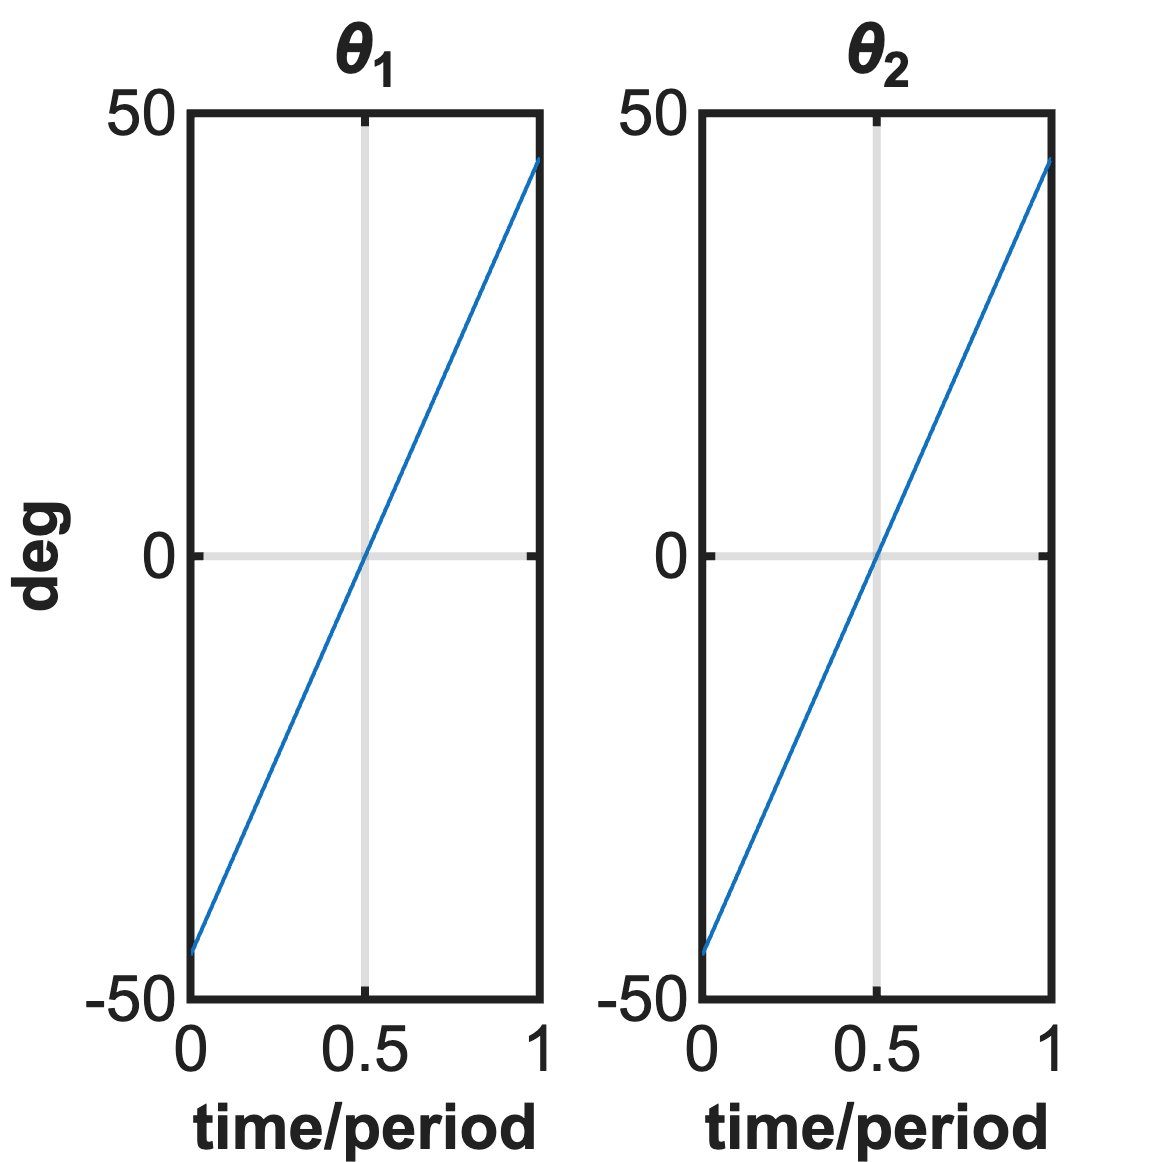

t = linspace(0,2*pi,90);
%theta1 = pi/4*sin(t);
theta1 = linspace(-pi/4,pi/4,90);
theta2 = linspace(-pi/4,pi/4,90);
figure;
subplot(1,2,1);
plot(t/(2*pi), theta1*180/pi, 'LineWidth', 1.5);
title('\theta_1');
ylabel('deg'); xlabel('time/period'); grid on;

subplot(1,2,2);
plot(t/(2*pi), theta2*180/pi, 'LineWidth', 1.5);
title('\theta_2');
xlabel('time/period'); grid on;
improvePlot;

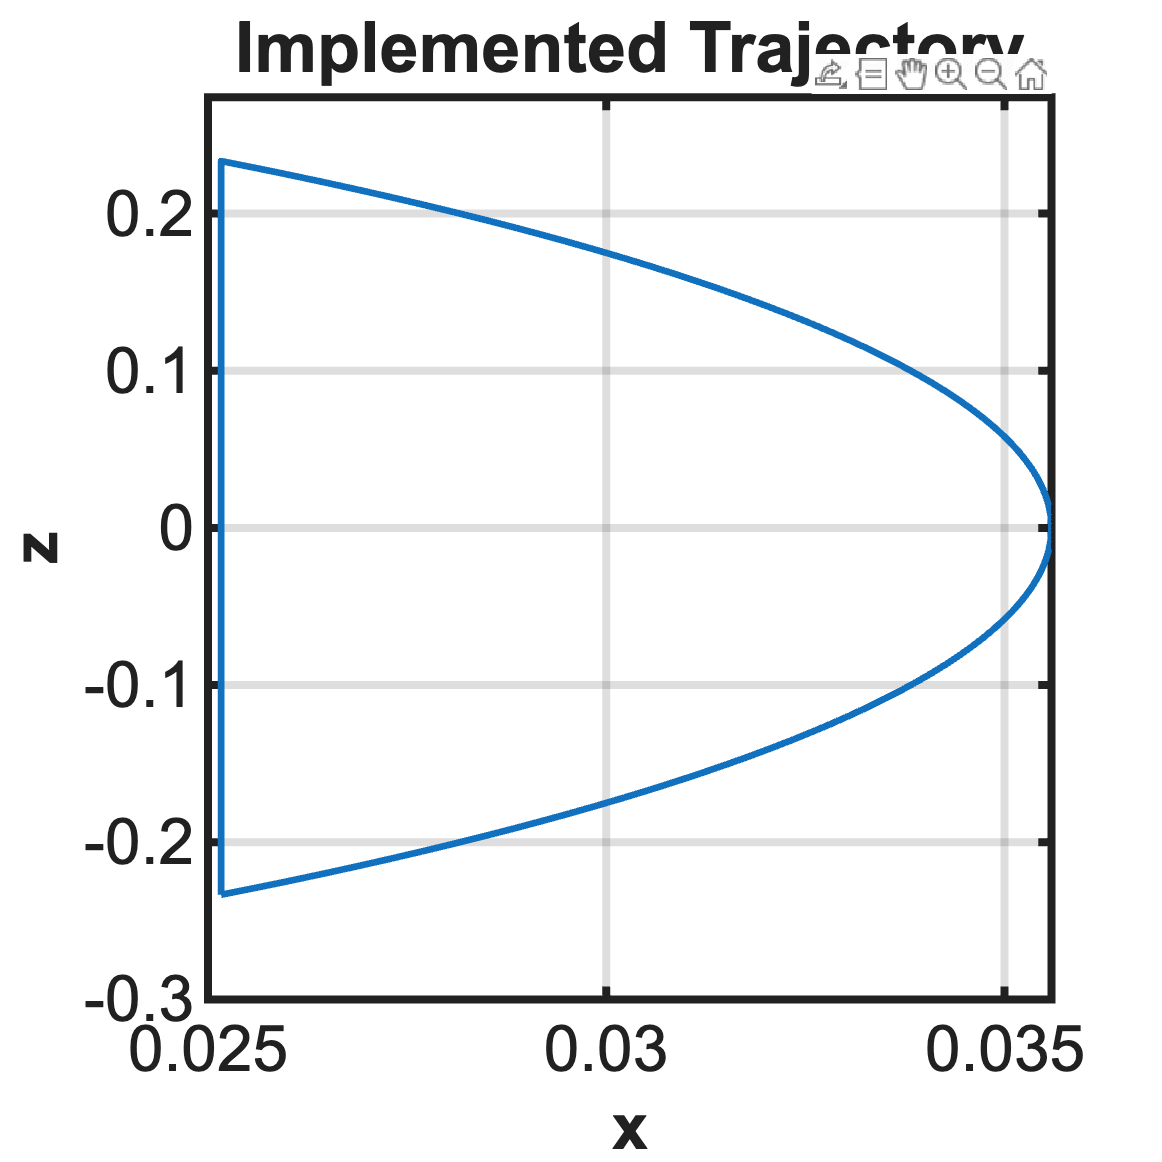


theta1 = [theta1,-pi/4];
theta2 = [theta2,-pi/4];
%theta2 = pi/4*sin(t+pi/5);
l2 = 0.313;
d1 = 0.034;
d2 = 0.03559;
l1 = .355265 - l2;
qmnew = subs(qm1);
figure;
plot(qmnew(1,:),qmnew(3,:));
xlabel('x'); ylabel('z');
title('Implemented Trajectory'); grid on;
improvePlot;

## Inverse Kinematics

syms xprime y z real

x = xprime + d2 - d1;
c2 = (x+d1)/d2;
s2 = sqrt(1-c2^2);
%theta2 = atan2(s2,c2)*180/pi;
theta2 = acosd(c2)

$$theta2 = \frac{180\,\mathrm{acos}\left(\frac{d_{2}+\mathrm{xprime}}{d_{2}}\right)}{\pi }$$

% magnitude of argument must be less than or equal to 1
L = l1 +l2;
B = d2*sind(theta2);
%theta1 = atan2(z,y) + atan2(B,L)

$$theta1 = \text{atan2}\left(z,y\right)+\mathrm{atan}\left(\frac{d_{2}\,\sqrt{1-\frac{{\left(d_{2}+\mathrm{xprime}\right)}^{2}}{{d_{2}}^{2}}}}{l_{1}+l_{2}}\right)$$

theta1 = atan2(A*z+B*y,A*y-B*z);

$$theta1 = \text{atan2}\left(z\,\left(l_{1}+l_{2}\right)+d_{2}\,y\,\sqrt{1-\frac{{\left(d_{2}+\mathrm{xprime}\right)}^{2}}{{d_{2}}^{2}}},y\,\left(l_{1}+l_{2}\right)-d_{2}\,z\,\sqrt{1-\frac{{\left(d_{2}+\mathrm{xprime}\right)}^{2}}{{d_{2}}^{2}}}\right)$$


xprime = -d2; % example for validation
y = A;
z = -d2;
theta2 = subs(theta2)

$$theta2 = 90$$

theta1 = subs(theta1)

$$theta1 = 0$$

## Trajectory Following

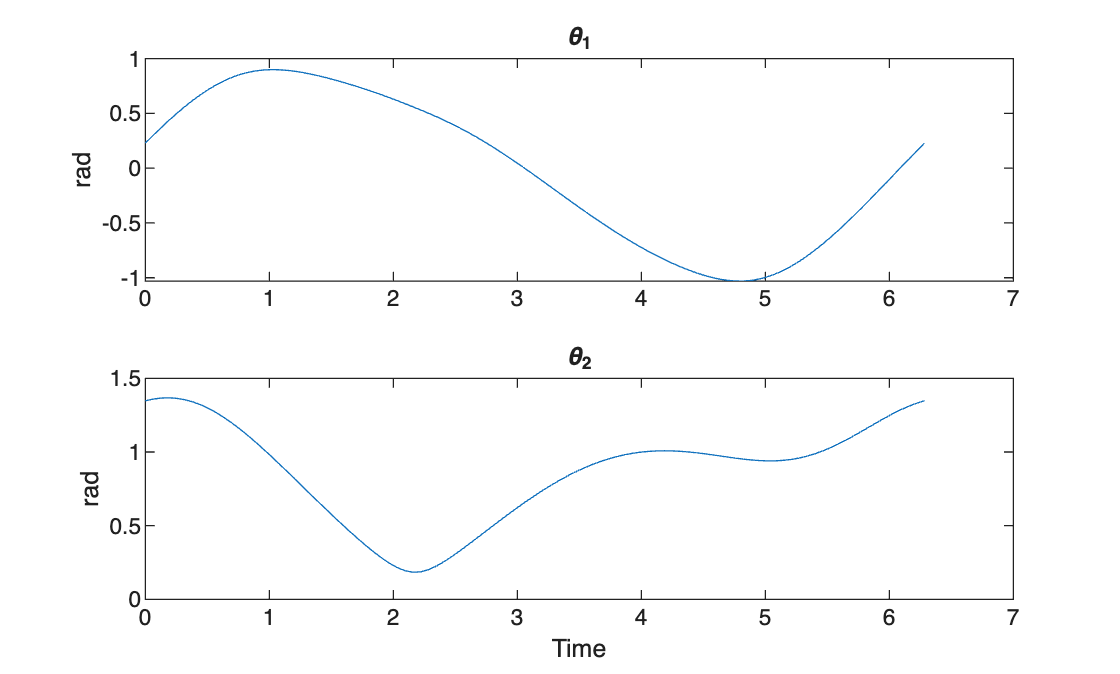

clc; clear; close all;

%% Robot Parameters
l2 = 0.313;
d1 = 0.034;
d2 = 0.03559;

L = .355265; %355mm in CAD
l1 = L-l2;

%% Time
period = 2*pi;
t = linspace(0, period, 100);

%% Desired Trajectory (x, z only)
phi = 0.75;
beta = -2;
a = sin(sin(-t));
b = - 0.5 * sin(sin(t) + t + 0.75);
x_d = 0.031*(a*cos(beta)-b*sin(beta)) + 0.0175;
z_d = 0.33 * (a*sin(beta)+b*cos(beta));

%% Storage
theta1 = zeros(size(t));
theta2 = zeros(size(t));

%% Loop through trajectory
for i = 1:length(t)
    
    x = x_d(i);
    z = z_d(i);

    %% ---- Step 1: Solve theta2 from x ----
    c2 = (x)/d2;

    % Check reachability
    if abs(c2) > 1
        warning('Unreachable point at t=%.2f', t(i));
        theta1(i) = NaN;
        theta2(i) = NaN;
        continue;
    end

    % Choose branch (+ or -)
    s2 = sqrt(1 - c2^2);   % try positive branch first

    theta2(i) = atan2(s2, c2);

    %% ---- Step 2: Solve theta1 from z ----
    A = L;
    B = d2 * s2;

    R = sqrt(A^2 + B^2);

    % Check reachability in z
    if abs(z) > R
        warning('Z out of range at t=%.2f', t(i));
        theta1(i) = NaN;
        continue;
    end

    phi = atan2(B, A);

    % Solve using asin
    theta1(i) = phi + asin(z / R);

end

%% Plot joint angles
figure;
subplot(2,1,1);
plot(t, theta1);
title('\theta_1');
ylabel('rad');

subplot(2,1,2);
plot(t, theta2);
title('\theta_2');
ylabel('rad');
xlabel('Time');

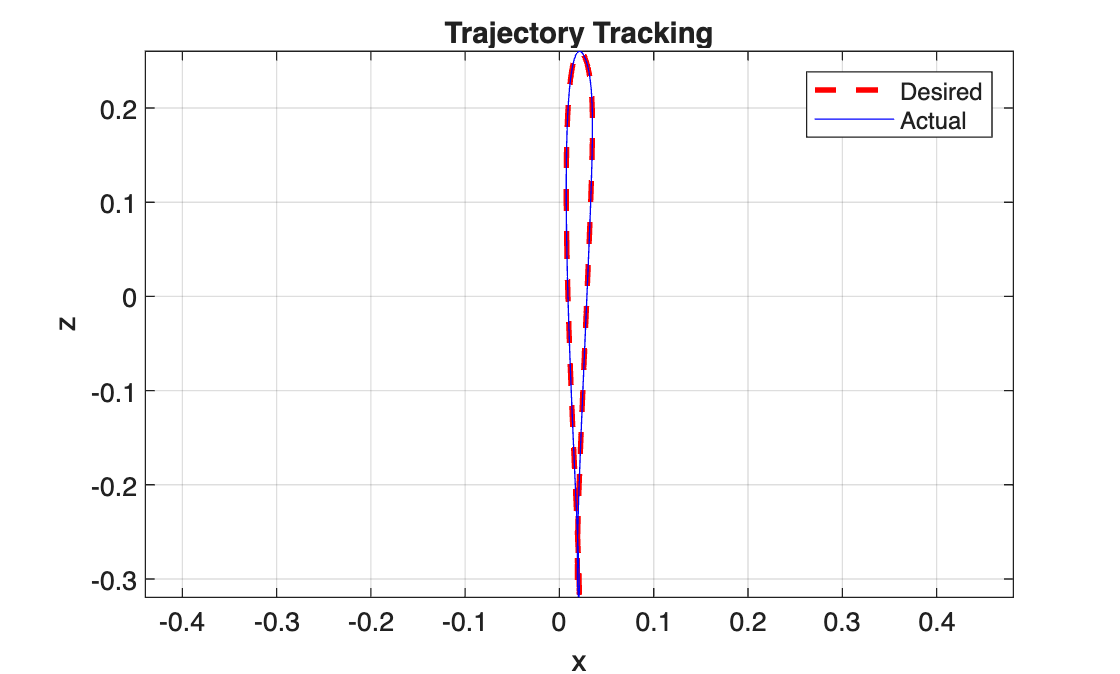


%% (Optional) Forward kinematics check
x_check = d2*cos(theta2);
z_check = L*sin(theta1) - d2*cos(theta1).*sin(theta2);

figure;
plot(x_d, z_d, 'r--', 'LineWidth', 2); hold on;
plot(x_check, z_check, 'b');
legend('Desired', 'Actual');
xlabel('x'); ylabel('z');
title('Trajectory Tracking');
axis equal;
grid on;

## Improved trajectory tracking

%% Robot Parameters
l2 = 0.313;
d1 = 0.034;
d2 = 0.03559;

L = .355265; %355mm in CAD
l1 = L-l2;

%% Time
period = 2*pi;
t = linspace(0, period, 100);

%% Desired Trajectory (x, z only)
phi = 0.75;
beta = -2;
a = sin(sin(-t));
b = - 0.5 * sin(sin(t) + t + 0.75);
x_d = 0.031*(a*cos(beta)-b*sin(beta)) + 0.0175;
z_d = 0.33 * (a*sin(beta)+b*cos(beta));

%% Storage
theta1 = zeros(size(t));
theta2 = zeros(size(t));
%% Inverse Kinematics with Branch Selection

for i = 1:length(t)

    x = x_d(i);
    z = z_d(i);

    % ---- Step 1: Solve theta2 candidates ----
    c2 = x/d2;  % redefined so origin coincides with servo2

    if abs(c2) > 1
        warning('Unreachable x at t=%.2f', t(i));
        theta1(i) = NaN;
        theta2(i) = NaN;
        continue;
    end

    s2_options = [sqrt(1 - c2^2), -sqrt(1 - c2^2)];

    candidates = [];

    % ---- Step 2: Build all IK candidates ----
    for s2 = s2_options

        theta2_cand = atan2(s2, c2);

        A = L;
        B = d2 * s2;
        R = sqrt(A^2 + B^2);

        if abs(z) > R
            continue;
        end

        phi = atan2(B, A);
        alpha = asin(z / R);

        % Two theta1 solutions
        theta1_cand_1 = phi + alpha;
        theta1_cand_2 = phi - alpha;

        candidates = [candidates;
            theta1_cand_1, theta2_cand;
            theta1_cand_2, theta2_cand];
    end

    % ---- Step 3: Select best candidate ----
    if i == 1
        % Initialize with first valid solution
        theta1(i) = candidates(1,1);
        theta2(i) = candidates(1,2);
    else
        theta1_prev = theta1(i-1);
        theta2_prev = theta2(i-1);

        best_cost = inf;

        for k = 1:size(candidates,1)
            % choose solution that is closest to previous position
            d1_err = wrapToPi(candidates(k,1) - theta1_prev);
            d2_err = wrapToPi(candidates(k,2) - theta2_prev);

            cost = d1_err^2 + d2_err^2;

            if cost < best_cost
                best_cost = cost;
                theta1(i) = candidates(k,1);
                theta2(i) = candidates(k,2);
            end
        end
    end

end

% Optional: unwrap for smooth plotting
theta1 = unwrap(theta1);
theta2 = unwrap(theta2);

## Checks and Plots

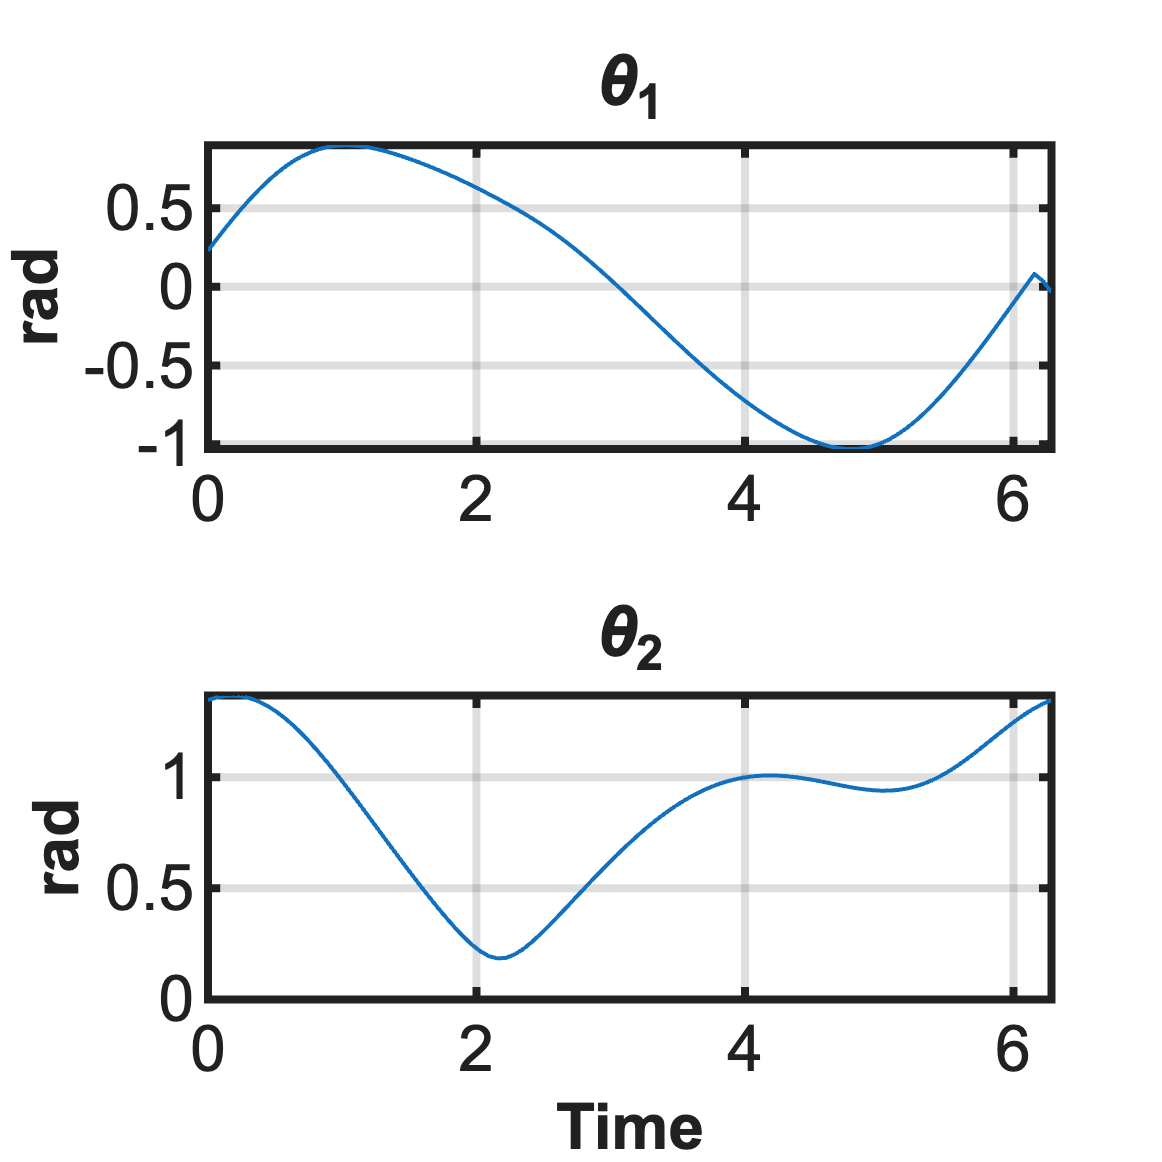

%% Forward Kinematics (for validation)

x_check = d2*cos(theta2);
z_check = L*sin(theta1) - d2*cos(theta1).*sin(theta2);

% (y is free, but we can compute it if curious)
y_check = L*cos(theta1) + d2*sin(theta1).*sin(theta2);

%% Plot Joint Angles
figure;
subplot(2,1,1);
plot(t, theta1, 'LineWidth', 1.5);
title('\theta_1');
ylabel('rad'); grid on;

subplot(2,1,2);
plot(t, theta2, 'LineWidth', 1.5);
title('\theta_2');
ylabel('rad'); xlabel('Time'); grid on;
improvePlot;

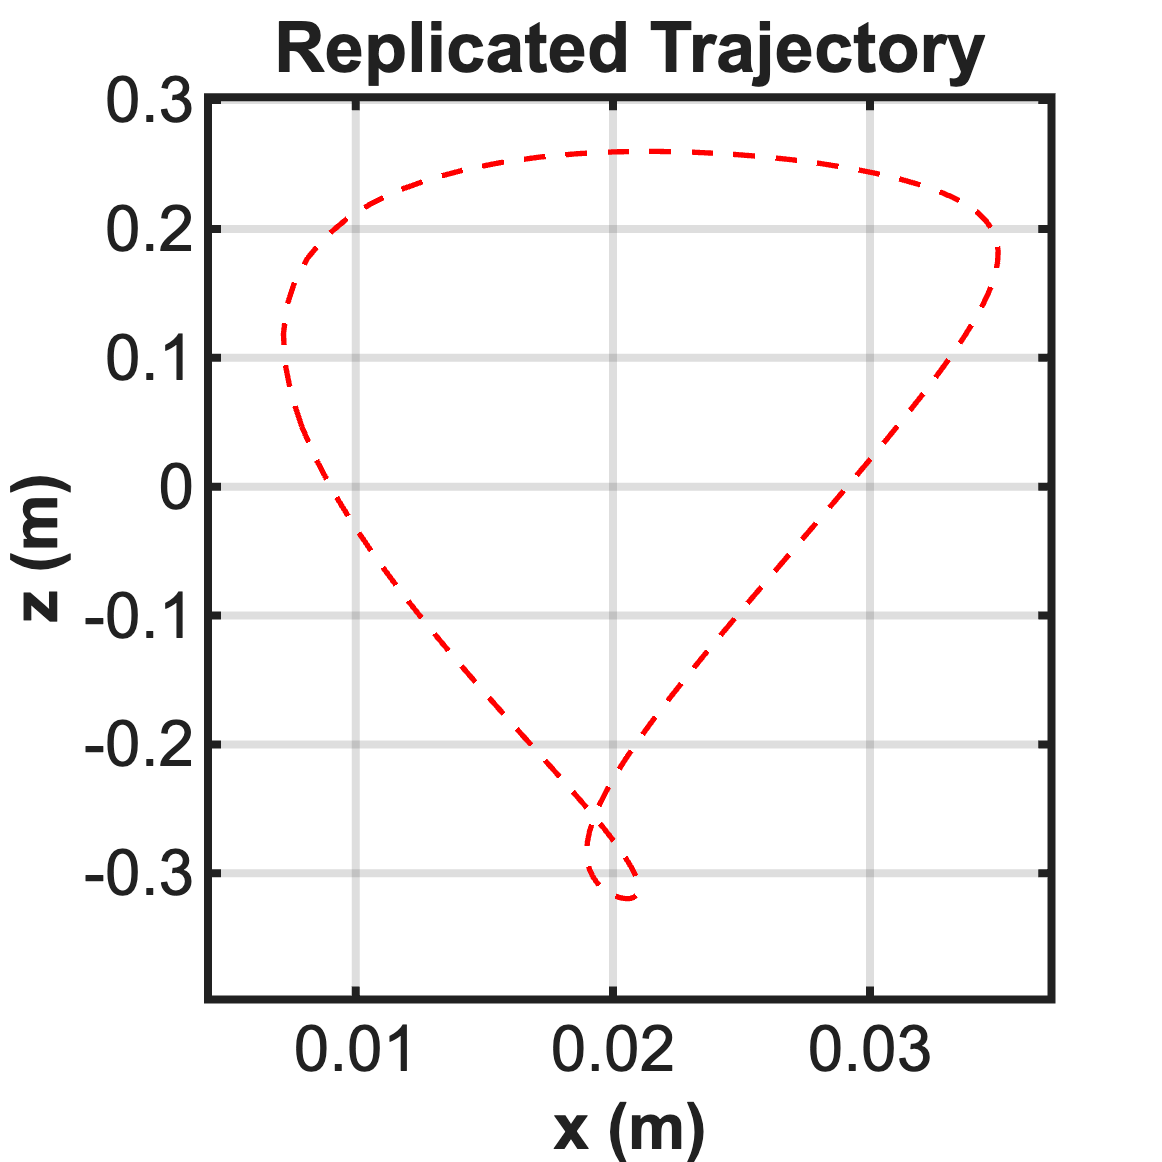


%% Compare Desired vs Actual
figure;
plot(x_d, z_d, 'r--', 'LineWidth', 2); hold on;
%plot(x_check, z_check, 'b', 'LineWidth', 1.5);

%legend('Desired', 'Actual');
xlabel('x (m)'); ylabel('z (m)');
title('Replicated Trajectory');
grid on;
improvePlot;

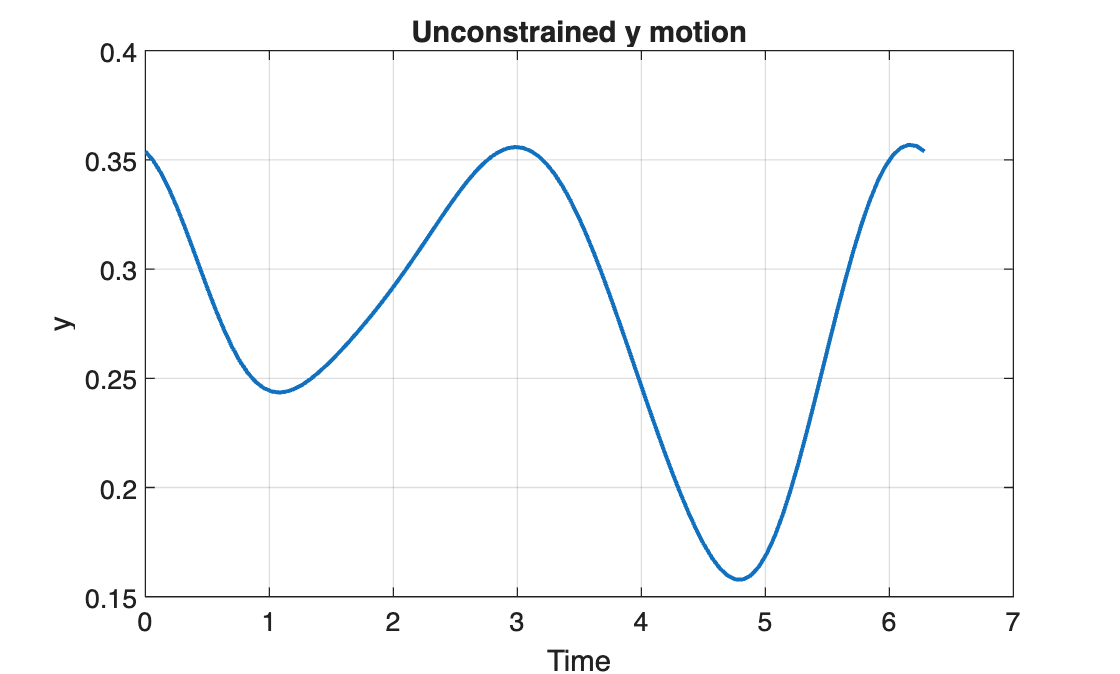


%% What happens to y?
figure;
plot(t, y_check, 'LineWidth', 1.5);
xlabel('Time');
ylabel('y');
title('Unconstrained y motion');
grid on;

## Data Offloading

% Assuming your 2x100 array is named 'my_data'
% Let's create dummy data for the sake of the example if you don't have it loaded
% my_data = rand(2, 100);

angle_data = [theta1;theta2];

% 1. Open a new header file to write to
fid = fopen('TrajectoryData.h', 'w');

% 2. Write the array declaration
fprintf(fid, 'const float angle_data[2][100] = {\n');

% 3. Loop through and format the rows and columns
for i = 1:2
    fprintf(fid, '  {');
    % Print all elements except the last one with a comma
    fprintf(fid, '%f, ', angle_data(i, 1:end-1));
    % Print the last element without a trailing comma
    fprintf(fid, '%f}', angle_data(i, end));
    
    % Add a comma after the first row, but not the second
    if i == 1
        fprintf(fid, ',\n');
    else
        fprintf(fid, '\n');
    end
end

% 4. Close the array and the file
fprintf(fid, '};\n');
fclose(fid);

disp('Export complete! Check your current folder for MatlabData.h');

Export complete! Check your current folder for MatlabData.h
